# **PCE-Bayesian Inference-Excavation deflection**

## **1 - INITIALIZE UQLAB**

clearvars;
uqlab;

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - RETRIEVE DATA SETS

X = input elastic modulus $E$ and loading position $\delta$ to begin PCE


X = xlsread("excavation_data",2);

Y = xlsread("excavation_data.xlsx",3);


## 3 - INPUT MODEL/PRIOR DISTRIBUTION OF THE MODEL PARAMETERS

PCE requires a choice of polynomial basis, a probabilistic input model needs to be defined. Specify the marginals of the probabilistic input model:

%Young's modulus 
InputOpt.Marginals(1).Name = 'Elastic modulus';
InputOpt.Marginals(1).Type = 'Gaussian';
InputOpt.Marginals(1).Moments = [210000000,30000000];

%loading position 
InputOpt.Marginals(2).Name = 'Loading position';
InputOpt.Marginals(2).Type = 'Gaussian';
InputOpt.Marginals(2).Moments = [0,1];

%Create an INPUT object based on the specified marginals:
myInput = uq_createInput(InputOpt);

## 4 - SURROGATE MODEL/POLYNOMIAL CHAOS EXPANSION (PCE) METAMODEL

Select PCE as the metamodeling tool:

MetaOpts.Type = 'Metamodel';
MetaOpts.MetaType = 'PCE';
MetaOpts.Method = 'LARS';
MetaOpts.TruncOptions.qNorm = 0.75;

Loop to the surrogate model; Use FEA data


MetaOpts.ExpDesign.X = X;
MetaOpts.ExpDesign.Y = Y;

Set the maximum polynomial degree to 5:

MetaOpts.Degree = 2:10;

Create the metamodel object and add it to UQLab:

mySurrogateModel  = uq_createModel(MetaOpts);

---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 1
Final LOO error estimate: 3.042282e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 7 and qNorm 0.75 for output variable 2
Final LOO error estimate: 1.093585e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 3
Final LOO error estimate: 5.376560e-04
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 6 and qNorm 0.75 for output variable 4
Final LOO error estimate: 1.352357e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 4 and qNorm 0.75 for output variable 5
Final LOO error estimate: 1.221514e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 6
Final LOO error estimate: 2.801315e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---


The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 7
Final LOO error estimate: 5.925357e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 4 and qNorm 0.75 for output variable 8
Final LOO error estimate: 2.236863e-03
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 4 and qNorm 0.75 for output variable 9
Final LOO error estimate: 2.066843e-03
---                 Calculation finished!                               ---


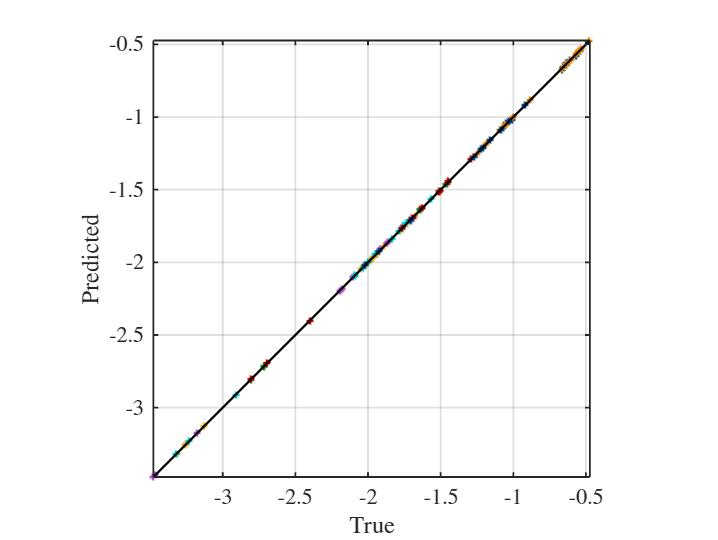

%Plot the ture vs. predicted values
YPCE = uq_evalModel(mySurrogateModel,X);
uq_plot(Y,YPCE,'+');
hold on;
uq_plot([min(Y) max(Y)], [min(Y) max(Y)], 'k');
axis equal;
axis([min(Y(:)) max(Y(:)) min(Y(:)) max(Y(:))]);
xlabel('True');ylabel('Predicted');
hold off;

## 5 - MEASUREMENT DATA

myData.y =  xlsread("excavation_data.xlsx",4)';
myData.Name = 'middleDeflection';
position = 1:9

position =      1     2     3     4     5     6     7     8     9


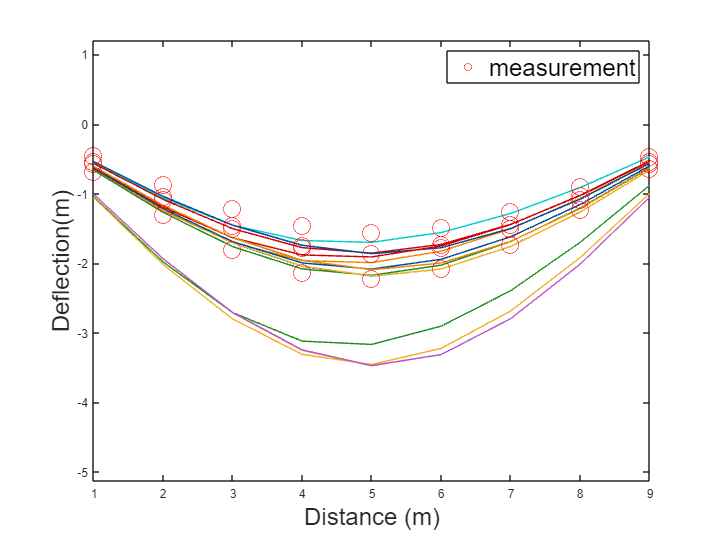

for i = 1:size(X,1)
    
    p = plot(position',Y(i,:)');
    hold on

end
axis equal;
xlabel('Distance (m)','FontSize',20);ylabel('Deflection(m)',"FontSize",20);
q = scatter(position,myData.y,200,'r','o');

legend(q(1),'measurement','FontSize',20) ;
hold off;

## 6 - BAYESIAN ANALYSIS

%The options of the Bayesian inversion analysis are specified with the following structure:BayesOpts.Type = 'Inversion';
BayesOpts.Type = 'Inversion';
BayesOpts.Data = myData;

%Run the Bayesian inversion analysis:
myBayesianAnalysis = uq_createAnalysis(BayesOpts);

The discrepancy was not specified,
using unknown i.i.d. Gaussian discrepancy...
The solver was not specified, using MCMC
The sampler was not specified, using affine invariant ensemble sampler
Starting AIES...

|##############################| 100.00%

Finished AIES!


%print and display
uq_postProcessInversion(myBayesianAnalysis,'priorPredictive',1000);
uq_print(myBayesianAnalysis);

%----------------------- Inversion output -----------------------%
   Number of calibrated model parameters:         2
   Number of non-calibrated model parameters:     0

   Number of calibrated discrepancy parameters:   9

%------------------- Data and Discrepancy
%  Data-/Discrepancy group 1:
   Number of independent observations:            4

   Discrepancy:
      Type:                                       Gaussian
      Discrepancy family:                         Row
      Discrepancy parameters known:               No

   Associated outputs:
      Model 1: 
         Output dimensions:                       1
                                                  to
                                                  9


%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:08
   Number of sample points:                       3.00e+04

%----------

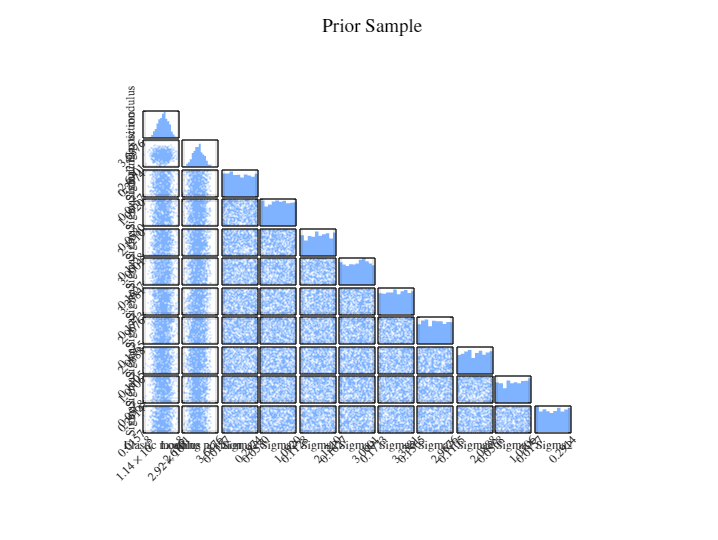

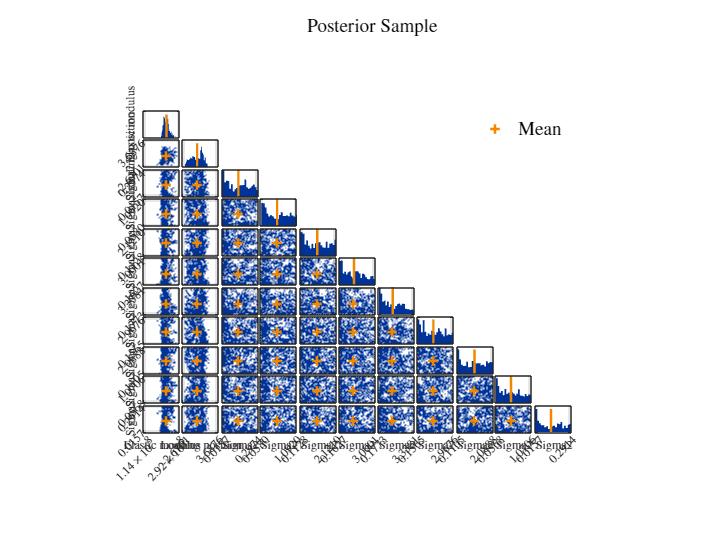

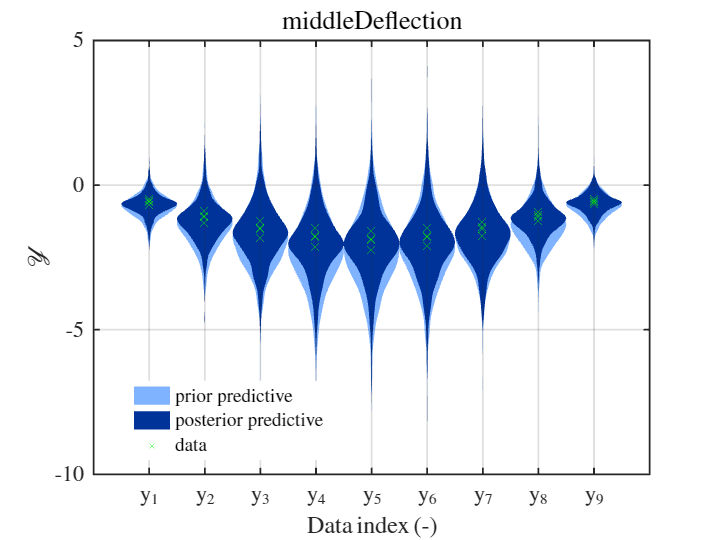

uq_display(myBayesianAnalysis);